% (C) Copyright 2020 Murilo Marques Marinho
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho - murilo@nml.t.u-tokyo.ac.jp

# Robot Control Basics using DQ Robotics - Part 2

## Introduction

In the last lesson, I introduced you to the basics of kinematic modeling and kinematic control using a 1-DoF planar robot. The main point of that lesson was to teach you how to develop your robots from scratch, if needed.

Nonetheless, the DQ Robotics library has many of those functionalities built-in. In this lesson, you will learn how to model serial manipulators using the Denavit-Hartenberg parameters and how to calculate important Jacobians using DQ Robotics. You will also learn how to create a basic kinematic controller using DQ Robotics.

## Notation

Keep these in mind (we will also use this notation when writting papers to conferences and journals):

- ${\bf h} \in\mathbb{H}$: a quaternion. (Bold-face, lowercase character)

- $\underline{{\bf h}}\in\mathcal{H}$: a dual quaternion. (Bold-face, underlined, lowercase character)

- ${\bf{p}},{\bf{t}},\cdots\in \mathbb{H}_p$: pure dual quaternions. They represent points, positions, and translations. They are quaternions for which $\text{Re}\left({\bf h}\right)=0$.

- ${\bf r}\in\mathbb{S}^3$: unit quaternions. They represent orientations and rotations. They are quaternions for which $||{\bf h}||=1$. 

- $\underline{{\bf x}} \in$$\underline{\mathcal{S}}$: unit dual quaternions. They represent poses and pose transformations. They are dual quaternions for which $||{\bf h}||=1$.

- $\underline{{\bf l}}\in \mathcal{H}_p\cap$$\underline{\bf{\mathcal{S}}}$: a Plücker line. 

- $\underline{{\bf \pi}}\in \left\{ P\left(\underline{{\bf \pi}}\right) \in \mathbb{H}_p\right\}\cap\underline{\bf{\mathcal{S}}}$: a plane.

## Problem Definition

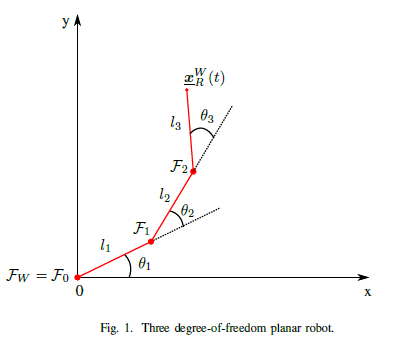

- Let the robot $R$ be a 3-DoF planar robot, as draw in Fig.1. 

- Let $\mathcal{F}_W$ be the world-reference frame. 

- Let $\underline{\bf{x}}_R(t)\triangleq\underline{\bf{x}}_R$ $\in$$\underline{\mathcal{S}}$ represent the pose of the *end effector*. 

- Let $R$ be composed of three rotational joints that rotates about their z-axis, composed in the joint-space vector ${\bf q}\left(t\right)\triangleq{\bf q}=\left[\theta_{1}\ \theta_{2}\ \theta_{3}\right]^{T}$ with $\theta_{1}\left(t\right)\triangleq\theta_{1},\theta_{2}\left(t\right)\triangleq\theta_{2},\theta_{3}\left(t\right)\triangleq\theta_{3}\in\mathbb{R}$. The rotation of the reference frames of each joint coincide with the rotation of $\mathcal{F}_W$ when $\theta_{1}=\theta_{2}=\theta_{3}=0$. The length of the joint is $l_1 ,l_2 ,l_3 \in$$\mathbb{R}^+-\{0\}$.

- Consider that we can freely control the joint vector ${\bf q}$.

Problems: 

- Obtain the (pose) foward kinematic model of the robot $R$ using a set of DH parameters.

- Obtain the pose Jacobian, rotation Jacobian, and translation Jacobian of $R$.

- Using 1. and 2., design a closed-loop pose controller, rotation controller, and translation controller.

## Modeling serial robots using Denavit-Hartenberg Parameters

In the last lesson, you modelled a 2-DoF planar robot. As the number of DoF and the complexity of the robots increase, modeling them requires a more general, systematic, and scalable strategy. In this lesson we will show how serial manipulators are modeled using the Denavit-Hartenberg (DH) parameters. This is the standard methodology used in DQ robotics for modeling serial robots. 

### Forward Kinematic Model using DH parameters

For robots in 3D space, the robot's pose is the most generic form of FKM for the end effector. When using unit dual quaternions, retrieving the rotation, translation, etc from the pose is quite straighforward. So let us obtain the pose FKM of the robot $R$ using the DH parameters.

Before going into detail about the DH parameters, let $\underline{{\bf x}}_{0}\in\underline{{\bf \mathcal{S}}}$ be the reference frame at the base of the robot. For convenience, it can coincide with the reference frame of the first joint of the robot. The first joint enacts a pose transformation of $\underline{{\bf x}}_{0}$ to the reference frame the second joint,  $\underline{{\bf x}}_{1}\in\underline{{\bf \mathcal{S}}}$, given by


$$\underline{{\bf x}}_{1}^{0}\left(\theta_{1}\right)\triangleq\underline{{\bf x}}_{1}^{0}\in\underline{{\bf \mathcal{S}}}$$


that depends on the joint value of the first joint. Given that the 3-DoF planar robot has three joints, the robot can be modeled with three consecutive transformations


$$\underline{{\bf x}}_{R}=\underline{{\bf x}}_{1}^{0}\underline{{\bf x}}_{2}^{1}\underline{{\bf x}}_{3}^{2},$$


where $\underline{{\bf x}}_{2}^{1}\left(\theta_{2}\right)\triangleq\underline{{\bf x}}_{2}^{1}\in\underline{{\bf \mathcal{S}}}$ and $\underline{{\bf x}}_{3}^{2}\left(\theta_{3}\right)\triangleq\underline{{\bf x}}_{3}^{2}\in\underline{{\bf \mathcal{S}}}$. This sequence of transformation is a methodology that can be used for a serial manipulator with any number of joints.

The DH parameters provide a systematic way to calculate each individual joint transformation of any n-DoF serial manipulator.  Each joint transformation, $\underline{{\bf x}}_{i+1}^{i}\left(\theta_{i}\right)\triangleq\underline{{\bf x}}_{i+1}^{i}\in\underline{{\bf \mathcal{S}}}$, with $i=1,2,3\ldotp \ldotp \ldotp n$ is composed of four intermediate transformations, as follows


$$\underline{{\bf x}}_{i+1}^{i}\triangleq\underline{{\bf x}}_{i'}^{i}\left(\theta_{i}\right)\underline{{\bf x}}_{i''}^{i'}\left(d_{i}\right)\underline{{\bf x}}_{i'''}^{i''}\left(a_{i}\right)\underline{{\bf x}}_{i+1}^{i'''}\left(\alpha_{i}\right),$$


where the DH parameters, for each joint, are $\theta_{i},d_{i},a_{i},\alpha_{i}\in\mathbb{R}$. Each of those parameters is related to one transformation. The first is the rotation of $\theta_i$ about the z-axis of the joint as follows


$$\underline{{\bf x}}_{i'}^{i}\left(\theta_{i}\right)=\cos\left(\frac{\theta_{i}}{2}\right)+\hat{k}\sin\left(\frac{\theta_{i}}{2}\right),$$


the second is a translation of $d_i$ about the z-axis of the transformed reference frame,


$$\underline{{\bf x}}_{i''}^{i'}\left(d_{i}\right)=1+\frac{1}{2}\hat{k}d_{i},$$


the third is the translation of $a_i$ about the x-axis of the transformed reference frame,


$$\underline{{\bf x}}_{i'''}^{i''}\left(a_{i}\right)=1+\frac{1}{2}\hat{\imath}a_{i},$$


the fourth, and last, is the rotation of $\alpha_i$ about the x-axis of the transformed reference frame


$$\underline{{\bf x}}_{i+1}^{i'''}\left(\alpha_{i}\right)=\cos\left(\frac{\alpha_{i}}{2}\right)+\hat{\imath}\sin\left(\frac{\alpha_{i}}{2}\right).$$


Back to our example, the following table summarizes the DH parameters of the 3-DoF planar robot.

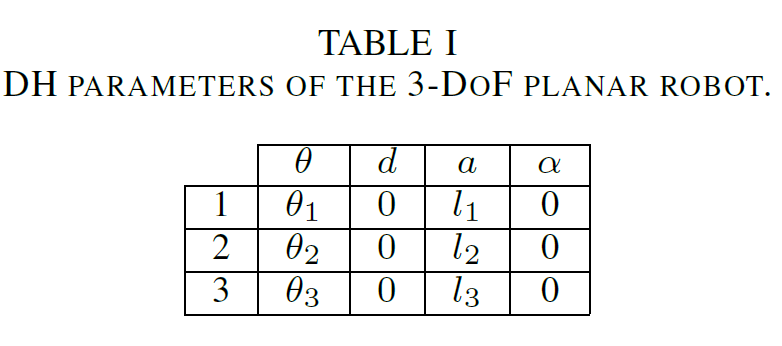

#### DQ Robotics Example

Let us create a class representing the 3-DoF planar robot using DH parameters. The good news is that most of the hard work is handled by DQ Robotics, using the following class

help DQ_SerialManipulatorDH

  Concrete class that extends the DQ_SerialManipulator using the
  Denavit-Hartenberg parameters (DH)
 
  Usage: robot = DQ_SerialManipulatorDH(A)
  - 'A' is a 4 x n matrix containing the Denavit-Hartenberg parameters
    (n is the number of links)
     A = [theta1 ... thetan;
             d1  ...   dn;
             a1  ...   an;
          alpha1 ... alphan;
          type1  ... typen]
  where type is the actuation type, either DQ_SerialManipulatorDH.JOINT_ROTATIONAL
  or DQ_SerialManipulatorDH.JOINT_PRISMATIC
  - The only accepted convention in this subclass is the 'standard' DH
  convention.
 
  If the joint is of type JOINT_ROTATIONAL, then the first row of A will
  have the joint offsets. If the joint is of type JOINT_PRISMATIC, then the
  second row of A will have the joints offsets.
 
  DQ_SerialManipulatorDH Methods (Concrete):
        get_

 Let us represent our robot in the following way, for $l_1=l_2=l_3=1$. 

Note that we use 

DQ_SerialManipulatorDH.JOINT_ROTATIONAL;

to define a rotational joint, so we do not explicilty define $\theta_1,\theta_2,\theta_3$ in our model.  

To calculate the forward kinematics model and plot the robot model, we can simply call the methods already available in the class, as follows

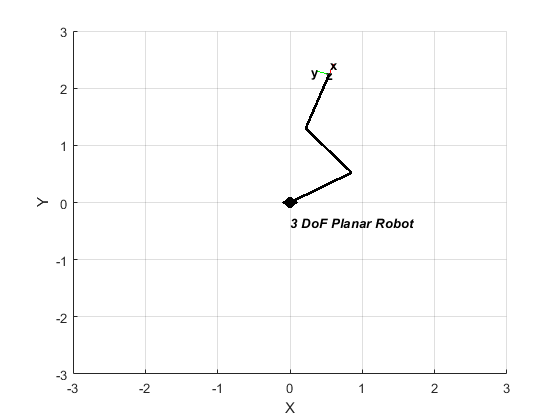

clear all;
close all;

% Initial joint values [rad]
theta1 = 0.55;
theta2 = 1.71;
theta3 = -1.02;

% Joint vector
q = [theta1 theta2 theta3];

% Instantiate the robot kinematics
three_dof_planar_robot = ThreeDofPlanarRobotDH.kinematics();

% Plot the robot in the xy-plane
three_dof_planar_robot.plot(q);


% Get the fkm, based on theta
x_r = three_dof_planar_robot.fkm(q);

For more details about the methods, check the documentation of the class using

help DQ_SerialManipulatorDH.fkm

    fkm(q) calculates the forward kinematic model and
    returns the dual quaternion corresponding to the
    end-effector pose. This function takes into account the
    displacement due to the base's and effector's poses.
 
    'q' is the vector of joint variables
    'to_ith_link' defines up to which link the fkm will be
    calculated. If to_ith_link corresponds to the last link,
    the method DOES NOT take into account the transformation
    given by set_effector. If you want to take into account
    that transformation, use fkm(q) instead.



help DQ_SerialManipulatorDH.plot

  plot(robot,q,options) plots the robot of type DQ_kinematics.
  q is the vector of joint configurations
  options is an optional argument that has variable size and accept any
  number of the following pairs:
 
   'workspace', W          size of robot 3D workspace, where
                           W = [xmn, xmx ymn ymx zmn zmx]
   'cylinder', C           color for joint cylinders, C=[r g b]
   'scale', scale          annotation scale factor
   'base'|'nobase'         controls display of base plane
   'wrist'|'nowrist'       controls display of wrist
   'name'|'noname'         display the robot's name
   'xyz'|'noa'             wrist axis label
   'joints'|'nojoints'     controls display of joints
 
  The graphical robot object holds a copy of the robot object and
  the graphical element is tagged with the robot's name (.name property).
 
  1) Figure behavior:
 
  If no robot of this name is currently displayed then a robot will
  be drawn in the current figure.  If hold is enabled (ho

### Differential Kinematics Model using DH parameters

Similar to how we calculated the the DFM in the last lesson, the DFM can be calculated for any set of DH parameters. 

#### Pose Jacobian

Using the FKM, we find


$$\text{vec}_{8}\left(\dot{\underline{{\bf x}}}_{R}\right)=\frac{\partial\left(\underline{{\bf x}}_{R}\right)}{\partial{\bf q}}\dot{{\bf q}},$$


where ${\bf J}_{{\bf \underline{x}}}\triangleq\frac{\partial\left(\underline{{\bf x}}_{R}\right)}{\partial{\bf q}}$ is the pose Jacobian. We do not need to worry about the details of how to calculate this for now. The details of how to calculate the Jacobian for any serial manipulator are described from Page 38 of

ADORNO, B. V., Two-arm manipulation: from manipulators to enhanced human-robot collaboration [*Contribution à la manipulation à deux bras : des manipulateurs à la collaboration homme-robot*], Université Montpellier 2, Montpellier, France, 2011. ([pdf](https://adorno.eng.ufmg.br/publications/phd_thesis_final_version.pdf)) 

#### Rotation Jacobian

The goal of this section is to find the rotation Jacobian, ${\bf J}_{r}$, so that the following relation holds


$$\text{vec}_{4}\left(\dot{{\bf r}}_{R}\right)={\bf J}_{r}\dot{{\bf q}}.$$


The rotation Jacobian is useful to control the rotation of the end effector and can be used to calculate many other Jacobians.

We can conveniently find the rotation Jacobian using the pose Jacobian. To do so, remember that the robot's end-effector pose can be decomposed as follows


$$\underline{{\bf x}}_{R}={\bf r}_{R}+\frac{1}{2}\varepsilon{\bf t}_{R}{\bf r}_{R}.$$


That means that the first-order time-derivative is 


$$\text{vec}_{8}\left(\dot{\underline{{\bf x}}}_{R}\right)\dot{{\bf q}}=\text{vec}_{8}P\left(\dot{\underline{{\bf x}}}_{R}\right)\dot{{\bf q}}+\text{vec}_{8}D\left(\dot{\underline{{\bf x}}}_{R}\right)\dot{{\bf q}}$$


that can be re-written as 


$${\bf J}_{{\bf \underline{x}}}\dot{{\bf q}}=\left[\matrix{ {\bf J}_{P\left({\bf \underline{x}}\right)} \cr 0} \right]\dot{{\bf q}}+\left[\matrix{ 0 \cr {\bf J}_{D\left({\bf \underline{x}}\right)}} \right]\dot{{\bf q}}$$


which means that the pose Jacobian can be decomposed as


$${\bf J}_{{\bf \underline{x}}}\dot{{\bf q}}=\left[\matrix{ {\bf J}_{P\left({\bf \underline{x}}\right)} \cr {\bf J}_{D\left({\bf \underline{x}}\right)}} \right]\dot{{\bf q}}.$$


Notice that 


$${\bf J}_{P\left({\bf \underline{x}}\right)}\dot{{\bf q}}=\text{vec}_{4}\left(\dot{{\bf r}}_{R}\right)$$



$${\bf J}_{P\left({\bf \underline{x}}\right)}\dot{{\bf q}}={\bf J}_{r}\dot{{\bf q}}$$


which means that the rotation Jacobian is  ${\bf J}_{r}={\bf J}_{P\left({\bf \underline{x}}\right)}$. That is, the rotational Jacobian is composed of the first four rows of the pose Jacobian.

#### Translation Jacobian

The goal of this section is to find the translation Jacobian, ${\bf J}_{t}$, so that the following relation holds


$$\text{vec}_{4}\left(\dot{{\bf t}}_{R}\right)={\bf J}_{t}\dot{{\bf q}}$$


The translation Jacobian is useful to control the translation of the end effector and can be used to calculate many other Jacobians. We can conveniently find the translation Jacobian using the pose Jacobian and the end-effector's pose.

We start from the translation relation


$${\bf t}_{R}=\text{translation}\left(\underline{{\bf x}}_{R}\right)=2D\left(\underline{{\bf x}}_{R}\right)P\left(\underline{{\bf x}}_{R}\right)^{*}$$



$$\dot{{\bf t}}_{R}=2\left[D\left(\dot{\underline{{\bf x}}}_{R}\right)P\left(\underline{{\bf x}}_{R}\right)^{*}+D\left(\underline{{\bf x}}_{R}\right)P\left(\dot{\underline{{\bf x}}}_{R}\right)^{*}\right]$$



$$\text{vec}_{4}\left(\dot{{\bf t}}_{R}\right)=2\left[\overset{-}{{\bf H}}_{4}\left(P\left(\underline{{\bf x}}_{R}\right)^{*}\right){\bf J}_{D\left({\bf \underline{x}}\right)}+\overset{+}{{\bf H}}_{4}\left(D\left(\underline{{\bf x}}_{R}\right)\right){\bf C}_{4}{\bf J}_{P\left({\bf \underline{x}}\right)}\right]\dot{{\bf q}}$$


hence


$${\bf J}_{t}=2\left[\overset{-}{{\bf H}}_{4}\left(P\left(\underline{{\bf x}}_{R}\right)^{*}\right){\bf J}_{D\left({\bf \underline{x}}\right)}+\overset{+}{{\bf H}}_{4}\left(D\left(\underline{{\bf x}}_{R}\right)\right){\bf C}_{4}{\bf J}_{P\left({\bf \underline{x}}\right)}\right].$$


#### DQ Robotics Example

The pose Jacobian can be computed using the DQ_SerialManipulatorDH class as follows.

% Get the pose Jacobian
Jx = three_dof_planar_robot.pose_jacobian(q)

Jx =    -0.2905   -0.2905   -0.2905
         0         0         0
         0         0         0
    0.4069    0.4069    0.4069
         0         0         0
   -0.3772   -0.4121    0.0867
    0.4356   -0.0632   -0.0286
         0         0         0


The rotation Jacobian and translation Jacobian can be calculated using methods of its DQ_Kinematics superclass. For instance, the rotation Jacobian can be obtained as

% Get the rotation Jacobian, based on the pose Jacobian
Jr = three_dof_planar_robot.rotation_jacobian(Jx)

Jr =    -0.2905   -0.2905   -0.2905
         0         0         0
         0         0         0
    0.4069    0.4069    0.4069


and the translation Jacobian can be obtained as

% Get the end-effector's pose
x = three_dof_planar_robot.fkm(q);
% Get the translation Jacobian
Jt = three_dof_planar_robot.translation_jacobian(Jx,x)

Jt =          0         0         0
   -2.2402   -1.7175   -0.9458
    0.5414   -0.3111    0.3248
         0         0         0


## Task-space position control 

In the last lesson you were introduced to the basics of robot control using the inverse differential kinematics model. 

Instead of building the controller from scratch, you can use controllers already available in DQ Robotics.

### Pseudo-Inverse Controller

In the last lesson, we implemented a simple pseudo-inverse-based kinematic controller. Let us revisit this topic using DQ Robotics. 

Let us start by cleaning up the workspace and write the control loop from scratch. 

#### Preliminaries

Let us start with the initial conditions of the problem.

First, clean the workspace.

clear all;
close all;
include_namespace_dq

Define the sampling time and how many seconds of control we will simulate.

% Sampling time [s]
tau = 0.01; 
% Simulation time [s]
final_time = 1;

Define the initial robot posture.

% Initial joint values [rad]
theta1 = -0.4;
theta2 = 1.71;
theta3 = 0.85;
% Arrange the joint values in a column vector
q_init = [theta1 theta2 theta3]';

Define the desired translation

% Desired translation components [m]
tx = 1.25;
ty = 1.25;
% Desired translation
td = tx*i_ + ty*j_;

then, the desired rotation.

% Desired rotation component [rad]
gamma = 0.49;
% Desired rotation
rd = cos(gamma/2.0) + k_*sin(gamma/2.0);

The desired pose will then be

% Desired pose
xd = rd + 0.5*E_*td*rd;

We then instantiate the robot kinematics, as follows.

% Create robot
three_dof_planar_robot = ThreeDofPlanarRobotDH.kinematics();

#### Translation Controller

The basic syntax to instantiate a translation controller is as follows. 

The robot will align the end-effector translation with the desired translation. The rotation is not controlled.

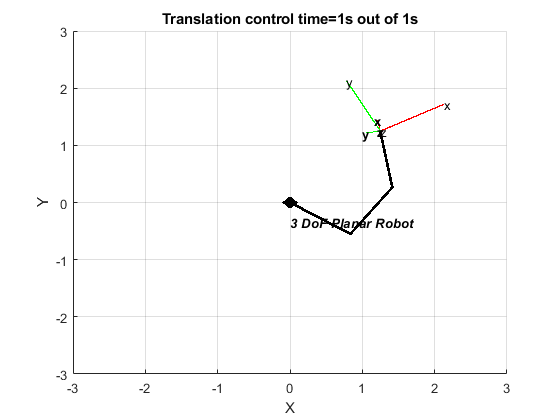

% Instanteate the controller 
translation_controller = DQ_PseudoinverseController(three_dof_planar_robot);
translation_controller.set_control_objective(ControlObjective.Translation);
translation_controller.set_gain(5.0);
translation_controller.set_damping(0); % Damping was not explained yet, set it as 0 to use pinv()

% Translation controller loop.
q = q_init;
for time=0:tau:final_time
    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec4(td));
    
    % Move the robot
    q = q + u*tau;
    
    
    % Plot
    % Plot the robot
    three_dof_planar_robot.plot(q);
    title(['Translation control' ' time=' num2str(time) 's out of ' num2str(final_time) 's'])
    % Plot the desired pose
    hold on
    plot(xd);
    hold off
    % [For animations only]
    drawnow; % [For animations only] Ask MATLAB to draw the plot now
end

% Rerun controller
 

#### Rotation Controller

The basic syntax to instantiate a rotation controller is as follows.

The robot will align the end-effector rotation with the desired rotation. The translation is not controlled.

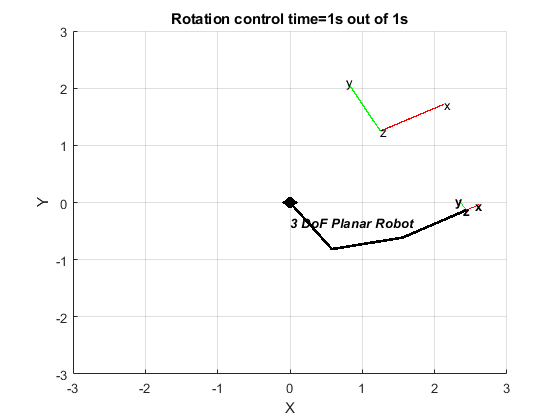

% Instanteate the controller 
translation_controller = DQ_PseudoinverseController(three_dof_planar_robot);
translation_controller.set_control_objective(ControlObjective.Rotation);
translation_controller.set_gain(5.0);
translation_controller.set_damping(0); % Damping was not explained yet, set it as 0 to use pinv()

% Rotation controller loop.
q = q_init;
for time=0:tau:final_time
    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec4(rd));
    
    % Move the robot
    q = q + u*tau;
    
    
    % Plot
    % Plot the robot
    three_dof_planar_robot.plot(q);
    title(['Rotation control' ' time=' num2str(time) 's out of ' num2str(final_time) 's'])
    % Plot the desired pose
    hold on
    plot(xd);
    hold off
    % [For animations only]
    drawnow; % [For animations only] Ask MATLAB to draw the plot now
end

% Rerun controller
 

#### Pose Controller

The basic syntax to instantiate a pose controller is as follows. 

The robot will align the end-effector pose with the desired pose. If the rotation and translation cannot be achieved simulatenously, the robot will balance rotation and translation error, according to the controller definitions.

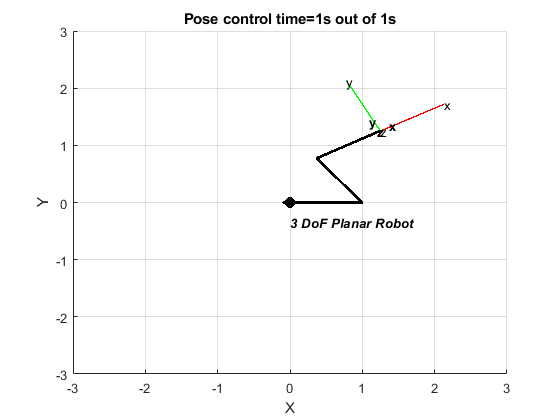

% Instantiate the controller 
translation_controller = DQ_PseudoinverseController(three_dof_planar_robot);
translation_controller.set_control_objective(ControlObjective.Pose);
translation_controller.set_gain(5.0);
translation_controller.set_damping(0); % Damping was not explained yet, set it as 0 to use pinv()

% Translation controller loop.
q = q_init;
for time=0:tau:final_time
    % Get the next control signal [rad/s]
    u = translation_controller.compute_setpoint_control_signal(q,vec8(xd));
    
    % Move the robot
    q = q + u*tau;
    
    
    % Plot
    % Plot the robot
    three_dof_planar_robot.plot(q);
    title(['Pose control' ' time=' num2str(time) 's out of ' num2str(final_time) 's'])
    % Plot the desired pose
    hold on
    plot(xd);
    hold off
    % [For animations only]
    drawnow; % [For animations only] Ask MATLAB to draw the plot now
end

% Rerun controller
 

# Homework

(1) Following the format of [ThreeDofPlanarRobotDH.m], create a class called [NDofPlanarRobotDH.m] as shown in the figure. 

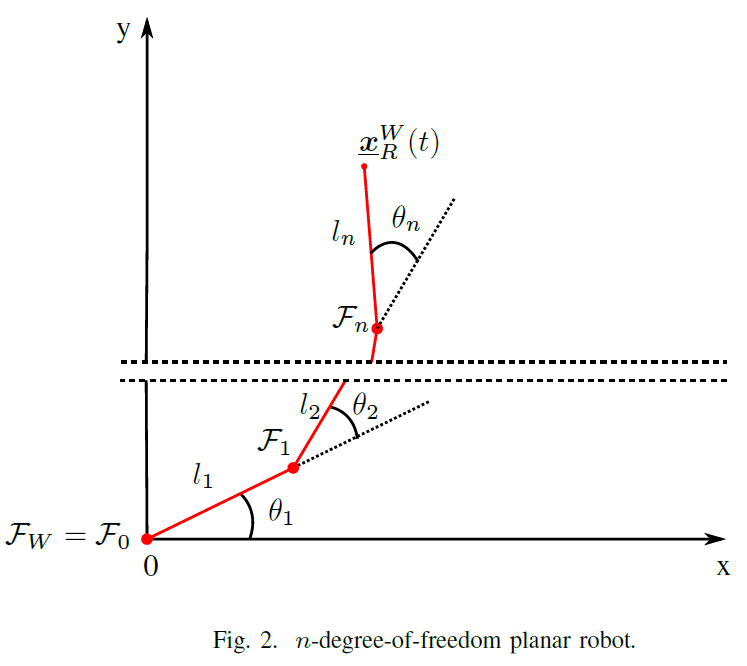

The class must

- Consider all lengths of the links as unitary. That is, $l_{1}=l_2=\cdots=l_{n}=1$. 

- Have a "kinematics" method that takes the desired number of DoFs as input and returns the corresponding DQ_SerialManipulatorDH instance.

(2) Consider the desired translation ${\bf t}_d=5\hat{\imath}+2\hat{\jmath}$, desired rotation ${\bf r}_d=\cos\left(-\frac{\pi}{8}\right)+\hat{k}\sin\left(-\frac{\pi}{8}\right)$, and initial posture $\theta_i(0)=\frac{\pi}{8}$ for $ i=1...7$. Use the class you created in (1) to instantiate a 7-DoF planar robot.

- create a script called [seven_dof_planar_robot_translation_control.m] that implements a task-space translation controller using a DQ_PseudoinverseController. Control the 7-DoF planar robot to ${\bf t}_{d}.$

- create a script called [seven_dof_planar_robot_rotation_control.m] that implements a task-space rotation controller using a DQ_PseudoinverseController. Control the 7-DoF planar robot to ${\bf r}_{d}.$

- create a script called [seven_dof_planar_robot_pose_control.m] that implements a task-space pose controller using a DQ_PseudoinverseController. Control the 7-DoF planar robot to $\underline{{\bf x}}_{d}={\bf r}_{d}+\frac{1}{2}\varepsilon{\bf t}_{d}{\bf r}_{d}$.